Q1 part 1

syms x1 x2 x3 u;

R = 10; 
L = 1.15e-01;
g = 9.81; 
M = 0.0844;
c = 7000; 
yd = 0.002;

eq1 = x2 == 0

$$eq1 = x_{2}=0$$

eq2 = -g+c*x3^2/(0.0072-x1)/M == 0

$$eq2 = -\frac{17500000\,{x_{3}}^{2}}{211\,\left(x_{1}-\frac{9}{1250}\right)}-\frac{981}{100}=0$$

eq3 = 1/L*(-R*x3+u) == 0

$$eq3 = \frac{200\,u}{23}-\frac{2000\,x_{3}}{23}=0$$

eq4 = x1 == yd

$$eq4 = x_{1}=\frac{1}{500}$$

sol = solve([eq1,eq2,eq3,eq4],[x1 x2 x3 u]);

x1_star_temp = double(sol.x1)

x1_star_temp =     0.0020
    0.0020


x2_star_temp = double(sol.x2)

x2_star_temp =      0
     0


x3_star_temp = double(sol.x3)

x3_star_temp = 	1.0e+-3 *

   -0.7843
    0.7843


u_star_temp = double(sol.u)

u_star_temp =    -0.0078
    0.0078


Q1 part 2

x1_star = 0.002;
x2_star = 0;
x3_star = 0.0007843;
u_star = 0.0078;
y_star = x1_star;


A = [0, 1, 0;c/M*x3_star^2/(0.0072-x1_star)^2, 0, c/M*x3_star*2/(0.0072-x1_star); 0, 0, -R/L]

A = 	1.0e+04 *

         0    0.0001         0
    0.1887         0    2.5019
         0         0   -0.0087


B = [0 0, 1/L]'

B =          0
         0
    8.6957


C = [1, 0, 0]

C =      1     0     0


D = 0

D = 0


x = [x1-x1_star, x2-x2_star, x3-x3_star]';
u

$$u = u$$

xdot = A*x + B*u

$$xdot = \left(\begin{array}{c} \bar{x_{2}}\\ \frac{4148997358798149\,\bar{x_{1}}}{2199023255552}+\frac{6877083471168677\,\bar{x_{3}}}{274877906944}-\frac{7414375830148863828815892777396481}{316912650057057350374175801344000}\\ \frac{200\,u}{23}-\frac{2000\,\bar{x_{3}}}{23}+\frac{904236336063150125}{13258597302978740224} \end{array}\right)$$

y = C*x + D*u - y_star

$$y = \bar{x_{1}}-\frac{1}{250}$$


s = tf('s');
gp = C*((s.*eye(3)-A)^-1)*B+D

gp =
 
               2.176e05
  -----------------------------------
  s^3 + 86.96 s^2 - 1887 s - 1.641e05
 
Continuous-time transfer function.



Q2 : STEP RESPONSE

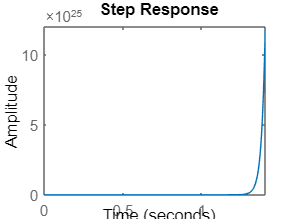

step(gp)

Q2 : PID

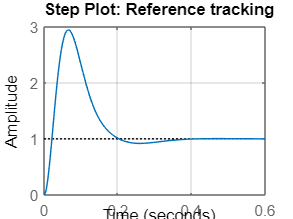

% Convert Response Time to Bandwidth
% Bandwidth is equivalent to 2 divided by the Response Time
wc = 2/0.0436888;

% Convert Transient Behavior to Phase Margin
% Phase Margin is equivalent to the Transient Behavior multiplied by 100
PM = 100*0.135774;

% Define options for pidtune command
opts = pidtuneOptions('PhaseMargin',PM);

% PID tuning algorithm for linear plant model
[C2,pidInfo] = pidtune(gp,'PID',wc,opts);

% Clear Temporary Variables
clear wc PM opts

% Get desired loop response
Response = getPIDLoopResponse(C2,gp,'closed-loop');

% Plot the result
stepplot(Response)
title('Step Plot: Reference tracking')
grid on


% Clear Temporary Variables
clear Response

Q2 : PID PARAMETERES NAD CONTROLLER

Kp = C2.Kp

Kp = 1.2377

Ki = C2.ki

Ki = 5.3762

Kd = C2.kd

Kd = 0.0311

N = 1000;
Gc = Kp + Ki*1/s + Kd*(N/(1+N*1/s))

Gc =
 
  32.32 s^2 + 1243 s + 5376
  -------------------------
        s^2 + 1000 s
 
Continuous-time transfer function.



Q2 : FINAL STEP RESPONSE AND SYSTEM INFO

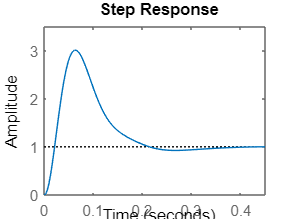

step(feedback(Gc*gp,1))

stepinfo(feedback(Gc*gp,1))

ans = struct with fields:
         RiseTime: 0.0134
    TransientTime: 0.3330
     SettlingTime: 0.3697
      SettlingMin: 0.9246
      SettlingMax: 3.0155
        Overshoot: 201.5520
       Undershoot: 0
             Peak: 3.0155
         PeakTime: 0.0622


stepinfo(out.Parameter_Simulation_Q2L.Data, out.tout)

ans = struct with fields:
         RiseTime: 0.0136
    TransientTime: 0.3329
     SettlingTime: 0.3703
      SettlingMin: 9.2344e-05
      SettlingMax: 3.0138e-04
        Overshoot: 201.6812
       Undershoot: 0
             Peak: 3.0138e-04
         PeakTime: 0.0646


stepinfo(out.Parameter_Simulation_Q2NL.Data, out.tout)

ans = struct with fields:
         RiseTime: 2.0350
    TransientTime: 52.4401
     SettlingTime: 52.2687
      SettlingMin: 6.9104e-05
      SettlingMax: 1.5571e-04
        Overshoot: 55.6874
       Undershoot: 0
             Peak: 1.5571e-04
         PeakTime: 23.1477


Q3

Ts = [5 0.1 0.01 0.001 ];

Gd_ZPmatched_T1 = c2d(Gc, Ts(1), 'matched')

Gd_ZPmatched_T1 =
 
  26.88 z^2 - 4.421e-10 z + 8.129e-83
  -----------------------------------
                z^2 - z
 
Sample time: 5 seconds
Discrete-time transfer function.



Gd_Bilinear_T1 = c2d(Gc, Ts(1), 'tustin')

Gd_Bilinear_T1 =
 
  14.69 z^2 + 26.84 z + 12.21
  ---------------------------
  z^2 - 0.0007997 z - 0.9992
 
Sample time: 5 seconds
Discrete-time transfer function.




Gd_ZPmatched_T2 = c2d(Gc, Ts(2), 'matched')

Gd_ZPmatched_T2 =
 
  1.423 z^2 - 0.9163 z + 0.03041
  ------------------------------
        z^2 - z + 3.72e-44
 
Sample time: 0.1 seconds
Discrete-time transfer function.



Gd_Bilinear_T2 = c2d(Gc, Ts(2), 'tustin')

Gd_Bilinear_T2 =
 
  2.116 z^2 - 0.7403 z - 0.3214
  -----------------------------
    z^2 - 0.03922 z - 0.9608
 
Sample time: 0.1 seconds
Discrete-time transfer function.




Gd_ZPmatched_T3 = c2d(Gc, Ts(3), 'matched')

Gd_ZPmatched_T3 =
 
  3.898 z^2 - 6.498 z + 2.654
  ---------------------------
      z^2 - z + 4.54e-05
 
Sample time: 0.01 seconds
Discrete-time transfer function.



Gd_Bilinear_T3 = c2d(Gc, Ts(3), 'tustin')

Gd_Bilinear_T3 =
 
  6.445 z^2 - 10.73 z + 4.373
  ---------------------------
    z^2 - 0.3333 z - 0.6667
 
Sample time: 0.01 seconds
Discrete-time transfer function.




Gd_ZPmatched_T4 = c2d(Gc, Ts(4), 'matched')

Gd_ZPmatched_T4 =
 
  20.83 z^2 - 40.86 z + 20.04
  ---------------------------
    z^2 - 1.368 z + 0.3679
 
Sample time: 0.001 seconds
Discrete-time transfer function.



Gd_Bilinear_T4 = c2d(Gc, Ts(4), 'tustin')

Gd_Bilinear_T4 =
 
  21.96 z^2 - 43.09 z + 21.13
  ---------------------------
    z^2 - 1.333 z + 0.3333
 
Sample time: 0.001 seconds
Discrete-time transfer function.




stepinfo(out.Parameter_Simulation.Data, out.tout)

ans = struct with fields:
         RiseTime: 0.0132
    TransientTime: 0.3174
     SettlingTime: 0.3616
      SettlingMin: 9.1682e-05
      SettlingMax: 3.1203e-04
        Overshoot: 212.0296
       Undershoot: 0
             Peak: 3.1203e-04
         PeakTime: 0.0630


stepinfo(out.Parameter_Simulation_Q2L.Data, out.tout)

ans = struct with fields:
         RiseTime: 0.0136
    TransientTime: 0.3329
     SettlingTime: 0.3703
      SettlingMin: 9.2344e-05
      SettlingMax: 3.0138e-04
        Overshoot: 201.6812
       Undershoot: 0
             Peak: 3.0138e-04
         PeakTime: 0.0646


Gd = Gd_ZPmatched_T4

Gd =
 
  20.83 z^2 - 40.86 z + 20.04
  ---------------------------
    z^2 - 1.368 z + 0.3679
 
Sample time: 0.001 seconds
Discrete-time transfer function.



stepinfo(out.Parameter_Simulation_Q3NL.Data, out.tout)

ans = struct with fields:
         RiseTime: 2.0347
    TransientTime: 52.4433
     SettlingTime: 52.2728
      SettlingMin: 6.9071e-05
      SettlingMax: 1.5574e-04
        Overshoot: 55.7176
       Undershoot: 0
             Peak: 1.5574e-04
         PeakTime: 23.1477


Q4

Gp_z = c2d(gp, Ts(4), 'matched')

Gp_z =
 
  5.21e-05 z^2 + 0.0001042 z + 5.21e-05
  -------------------------------------
   z^3 - 2.919 z^2 + 2.835 z - 0.9167
 
Sample time: 0.001 seconds
Discrete-time transfer function.



[num, den] = tfdata(Gp_z, 'v');
poles = roots(den)

poles =     1.0444
    0.9575
    0.9167


zeros = roots(num)

zeros =     -1
    -1


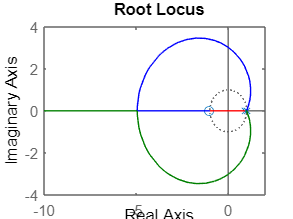

rlocus(Gp_z)

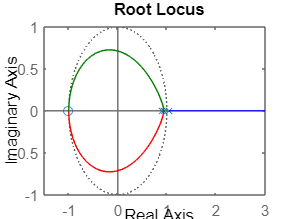

rlocus(-Gp_z)

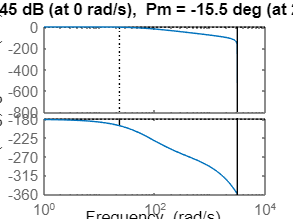

margin(Gp_z)


[Gm, Pm, Wcp, Wcg] = margin(Gp_z)

Gm = 0.7541

Pm = -15.5178

Wcp = 0

Wcg = 23.0526

BW = Wcg / (2 * pi)

BW = 3.6689

Q5

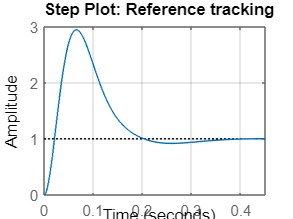

% Convert Response Time to Bandwidth
% Bandwidth is equivalent to 2 divided by the Response Time
wc2 = 2/0.0436888;

% Convert Transient Behavior to Phase Margin
% Phase Margin is equivalent to the Transient Behavior multiplied by 100
PM2 = 100*0.135774;

% Define options for pidtune command
opts2 = pidtuneOptions('PhaseMargin',PM2);

% PID tuning algorithm for linear plant model
[C3,pidInfo] = pidtune(Gp_z,'PID',wc2,opts2);

% Clear Temporary Variables
clear wc2 PM2 opts2

% Get desired loop response
Response2 = getPIDLoopResponse(C3,Gp_z,'closed-loop');

% Plot the result
stepplot(Response2)
title('Step Plot: Reference tracking')
grid on


% Clear Temporary Variables
clear Response2

Kp_z = C3.Kp

Kp_z = 1.2433

Ki_z = C3.ki

Ki_z = 5.3763

Kd_z = C3.kd

Kd_z = 0.0317

N_z = 1000;


z = tf(('z'),Ts(4))

z =
 
  z
 
Sample time: 0.001 seconds
Discrete-time transfer function.



Gd_z = Kp_z+Ki_z*Ts(4)*1/(z-1)+Kd_z*N_z/(1+N_z*Ts(4)/(z-1))

Gd_z =
 
  32.96 z^2 - 64.68 z + 31.72
  ---------------------------
            z^2 - z
 
Sample time: 0.001 seconds
Discrete-time transfer function.



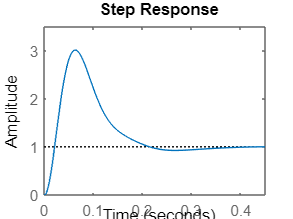

step(feedback(Gd_z*Gp_z,1))

stepinfo(feedback(Gd_z*Gp_z,1))

ans = struct with fields:
         RiseTime: 0.0130
    TransientTime: 0.3330
     SettlingTime: 0.3700
      SettlingMin: 0.9248
      SettlingMax: 3.0163
        Overshoot: 201.6255
       Undershoot: 0
             Peak: 3.0163
         PeakTime: 0.0630


stepinfo(feedback(Gc*gp,1))

ans = struct with fields:
         RiseTime: 0.0134
    TransientTime: 0.3330
     SettlingTime: 0.3697
      SettlingMin: 0.9246
      SettlingMax: 3.0155
        Overshoot: 201.5520
       Undershoot: 0
             Peak: 3.0155
         PeakTime: 0.0622


stepinfo([0;out.Parameter_Simulation_Q5.Data], out.tout)

ans = struct with fields:
         RiseTime: 0.0134
    TransientTime: 0.3326
     SettlingTime: 0.3695
      SettlingMin: 9.2478e-05
      SettlingMax: 3.0163e-04
        Overshoot: 201.6255
       Undershoot: 0
             Peak: 3.0163e-04
         PeakTime: 0.0630


stepinfo(out.Parameter_Simulation_Q5NL.Data, out.tout)

ans = struct with fields:
         RiseTime: 2.0351
    TransientTime: 52.4385
     SettlingTime: 52.2671
      SettlingMin: 6.9106e-05
      SettlingMax: 1.5571e-04
        Overshoot: 55.6850
       Undershoot: 0
             Peak: 1.5571e-04
         PeakTime: 23.1472


Q6

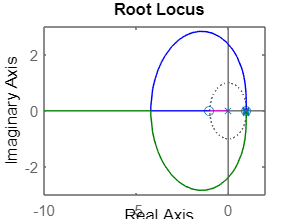

rlocus(feedback(Gd_z*Gp_z,1))

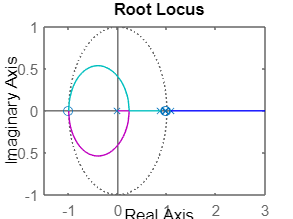

rlocus(feedback(-Gd_z*Gp_z,1))

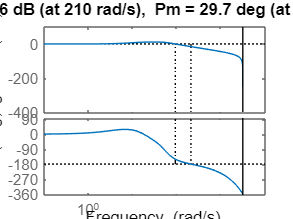

margin(feedback(Gd_z*Gp_z,1))


[Gm_z, Pm_z, Wcp_z, Wcg_z] = margin(feedback(Gd_z*Gp_z,1))

Gm_z = 6.0361

Pm_z = 29.6974

Wcp_z = 209.9890

Wcg_z = 93.1509

BW_Z = Wcg_z / (2 * pi)

BW_Z = 14.8254


[num, den] = tfdata(feedback(Gd_z*Gp_z,1), 'v');
poles_1 = roots(den)

poles_1 =    0.9734 + 0.0473i
   0.9734 - 0.0473i
   0.9859 + 0.0135i
   0.9859 - 0.0135i
  -0.0018 + 0.0000i


zeros_1 = roots(num)

zeros_1 =   -1.0000 + 0.0000i
  -1.0000 - 0.0000i
   0.9950 + 0.0000i
   0.9671 + 0.0000i


G_closeloop_z = feedback(Gd_z*Gp_z,1)

G_closeloop_z =
 
  0.001717 z^4 + 6.506e-05 z^3 - 0.003369 z^2 - 6.45e-05 z + 0.001653
  -------------------------------------------------------------------
     z^5 - 3.917 z^4 + 5.754 z^3 - 3.755 z^2 + 0.9167 z + 0.001653
 
Sample time: 0.001 seconds
Discrete-time transfer function.



Gd_z*Gp_z

ans =
 
  0.001717 z^4 + 6.506e-05 z^3 - 0.003369 z^2 - 6.45e-05 z + 0.001653
  -------------------------------------------------------------------
          z^5 - 3.919 z^4 + 5.754 z^3 - 3.752 z^2 + 0.9167 z
 
Sample time: 0.001 seconds
Discrete-time transfer function.



Q7